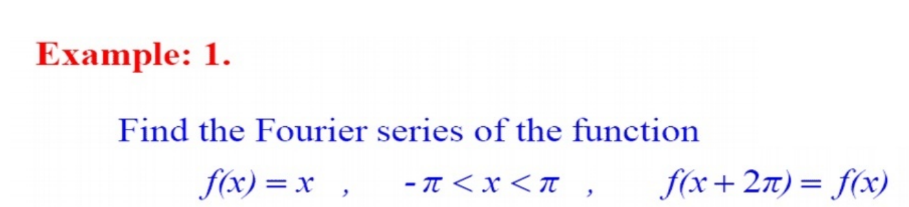

clear;clf;
syms x n;
f = x;
a0 = eval((1/pi)*int(f,x,[-pi pi]));
assume(n,"integer")
an = vpa(simplify((1/pi)*int(f*cos(n*x),x,[-pi pi])),3)

$$an = 0.0$$

bn = vpa(simplify((1/pi)*int(f*sin(n*x),x,[-pi pi])),3)

$$bn = -\frac{2.0\,{\left(-1.0\right)}^{n}}{n}$$

f0 = vpa(simplify(an*cos(n*x)+bn*sin(n*x)),3)

$$f0 = -\frac{2.0\,{\left(-1.0\right)}^{n}\,\sin\left(n\,x\right)}{n}$$

fn = symsum(simplify(an*cos(n*x)+bn*sin(n*x)),n,1,inf)

$$fn = \left\{ \begin{array}{cl} 1.0\,\log\left({\mathrm{e}}^{-1.0\,x\,\mathrm{i}}+1.0\right)\,\mathrm{i}-1.0\,\log\left({\mathrm{e}}^{1.0\,x\,\mathrm{i}}+1.0\right)\,\mathrm{i} & \text{ if }x\in \mathbb{R}\wedge x\notin \left\{-6.283185307179586476925286766559\,k-3.1415926535897932384626433832795|k\in \mathbb{Z}\right\} \end{array}\right.$$

harm = 3;
for i = 1:harm
    fx = a0/2+symsum(f0,n,[1 i]);
    subplot(harm+1,1,i)
    fplot(fx,[-1 1])
    title('Harmonic')
    xlabel('time')
end
hold on

**Plot Input**

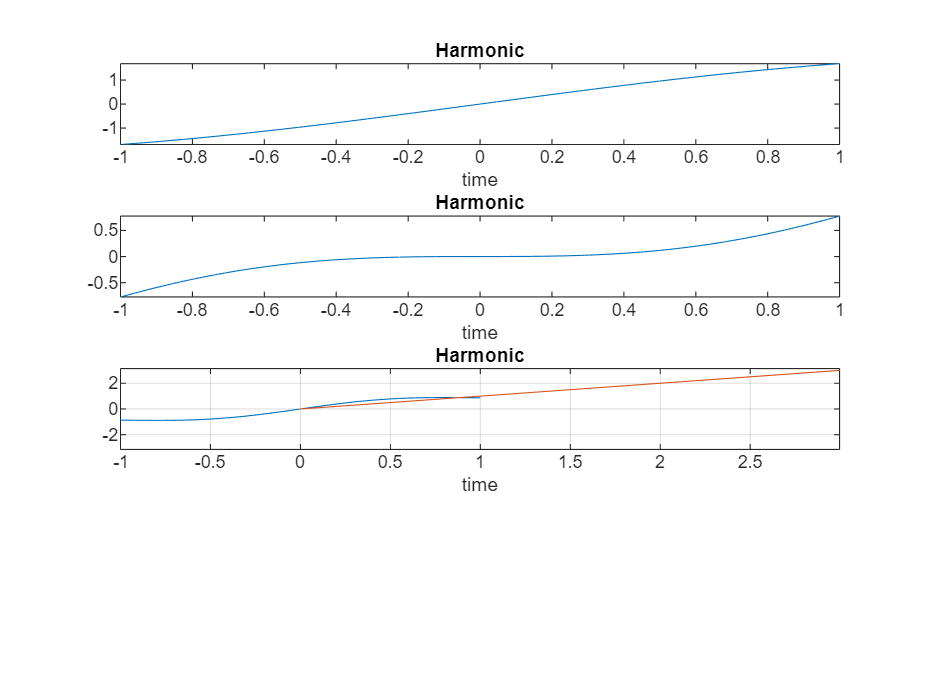

t = -pi/1000:pi;
y = t;
plot(t,y)
ylim([-pi pi])
grid on